%{
%ขั้นตอนการเก็บค่าจากการทดลอง
saveV_LMin = out.v_simout(:,1) %รับค่า out.v_simout จาก Simulink ลงในตัวแปรที่กำหนด
saveA_LMin = out.A_simout(:,1) %รับค่า out.A_simout จาก Simulink ลงในตัวแปรที่กำหนด
save("LMin_NosheildS8","saveV_LMin","saveA_LMin"); %บันทึกค่าลงในตัวแปรที่กำหนด
%}

%{
alldata = ["LMin_NosheildS1.mat","LMin_NosheildS2.mat","LMin_NosheildS3.mat","LMin_NosheildS4.mat","LMin_NosheildS5.mat","LMin_NosheildS6.mat","LMin_NosheildS7.mat","LMin_NosheildS8.mat"];
dataA = [];
dataV = [];

for i = 1:8
    load(alldata(i),"saveA_LMin","saveV_LMin");
    %Get a raw data

    sumA = 0;
    sumV = 0;
    for j = 1:101
        sumA = sumA + saveA_LMin(j);
        sumV = sumV + saveV_LMin(j);
    end
    %Sum a data

    avgA = sumA / 101;
    avgV = sumV / 101;
    %Get an average

    dataA(i) = avgA;
    dataV(i) = avgV;
    %Get the data in matrix
end

save("dataLMin_Nosheild","dataA","dataV");
%}

Non-Linear Graph


% Load the data
alldata = {"dataLMax_Nosheild.mat","dataLMax_sheild.mat","dataLMin_Nosheild.mat","dataLMin_sheild.mat"}

alldata = 1×4 cell array
    {["dataLMax_Nosheild.mat"]}    {["dataLMax_sheild.mat"]}    {["dataLMin_Nosheild.mat"]}    {["dataLMin_sheild.mat"]}


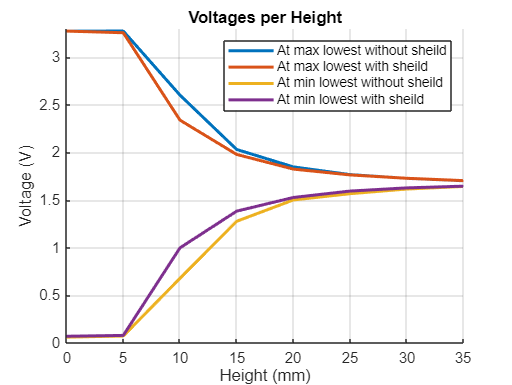


% Create the figure and plot the data
figure;
hold on;
for m = 1:4 
    load(alldata{m});
    plot([0 5 10 15 20 25 30 35], dataV,'LineWidth',2);
end
% Set axis limits
xlim([0 35]);
ylim([0 3.3]);

% Add labels and title
xlabel('Height (mm)');
ylabel('Voltage (V)');
title('Voltages per Height');
legend('At max lowest without sheild','At max lowest with sheild','At min lowest without sheild','At min lowest with sheild')
% Turn on grid lines
grid on;

%}

**Calculate magnetic flux density**

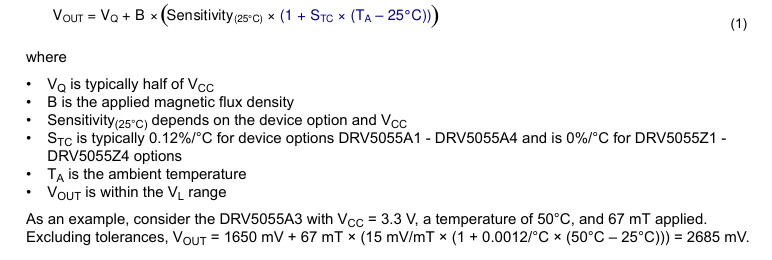


alldata = {"dataLMax_Nosheild.mat","dataLMax_sheild.mat","dataLMin_Nosheild.mat","dataLMin_sheild.mat"}

%flux_max_ns = [];
%flux_max_s = [];
flux_min_ns = [];
%flux_min_s = [];

B=0; %Magnetic flux density
TA=25; % Temp ambient
STC=0.0360; % 0.12%/C A2=30C So STC=3.6%,0.0360
Sensitivty = 30; 
Vq=1650; % half of Vcc(3.3)

    load(alldata{4});
    for i=1:8
        Vout=(dataV(i)*1000);
        B=(Vout-Vq)/(Sensitivty*(1+STC*(TA-25))); % mT = milliTesla
       flux_min_ns(i)=B;
    end
%}


Plot flux density


% Load the data
alldata = {"flux_max_ns.mat","flux_max_s.mat","flux_min_ns.mat","flux_min_s.mat"}

alldata = 1×4 cell array
    {["flux_max_ns.mat"]}    {["flux_max_s.mat"]}    {["flux_min_ns.mat"]}    {["flux_min_s.mat"]}


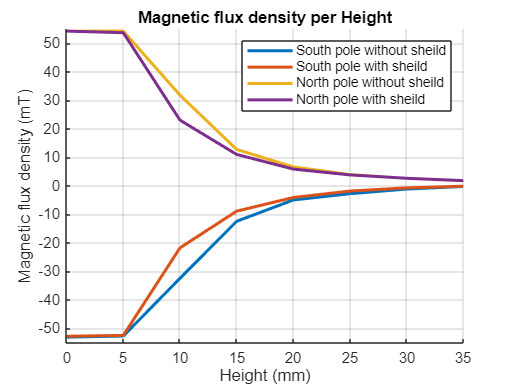


% Create the figure and plot the data
figure;
hold on;

load(alldata{m});
plot([0 5 10 15 20 25 30 35], flux_min_ns,'LineWidth',2);
plot([0 5 10 15 20 25 30 35], flux_min_s,'LineWidth',2);
hold on;
plot([0 5 10 15 20 25 30 35], flux_max_ns,'LineWidth',2);
plot([0 5 10 15 20 25 30 35], flux_max_s,'LineWidth',2);


% Set axis limits
xlim([0 35]);
ylim([-55 55]);

% Add labels and title
xlabel('Height (mm)');
ylabel('Magnetic flux density (mT)');
title('Magnetic flux density per Height');
legend('South pole without sheild','South pole with sheild','North pole without sheild','North pole with sheild')
% Turn on grid lines
grid on;

%}


% Load the data
alldata = {"dataLMax_Nosheild.mat","dataLMax_sheild.mat","dataLMin_Nosheild.mat","dataLMin_sheild.mat"}

alldata = 1×4 cell array
    {["dataLMax_Nosheild.mat"]}    {["dataLMax_sheild.mat"]}    {["dataLMin_Nosheild.mat"]}    {["dataLMin_sheild.mat"]}


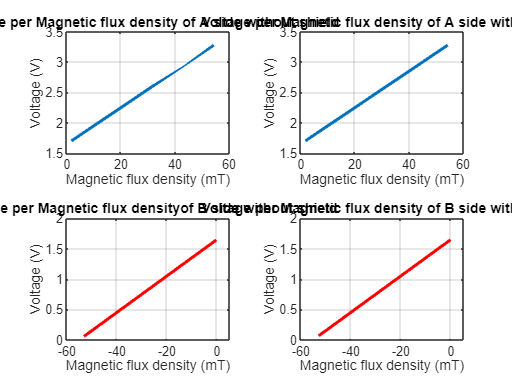


% Create the figure and plot the data
figure;
hold on;
load(alldata{1});
tiledlayout(2,2)
nexttile
plot(flux_max_ns, dataV,'LineWidth',2);

% Set axis limits
xlim([0 60]);
ylim([1.5 3.5]);
% Add labels and title
xlabel('Magnetic flux density (mT)');
ylabel('Voltage (V)');
title('Voltage per Magnetic flux density of A side without shield');
%legend('At max lowest without sheild','At max lowest with sheild','At min lowest without sheild','At min lowest with sheild')
% Turn on grid lines
grid on;

nexttile
load(alldata{2});
plot(flux_max_s, dataV,'LineWidth',2);

% Set axis limits
xlim([0 60]);
ylim([1.5 3.5]);
% Add labels and title
xlabel('Magnetic flux density (mT)');
ylabel('Voltage (V)');
title('Voltage per Magnetic flux density of A side with shield');
%legend('At max lowest without sheild','At max lowest with sheild','At min lowest without sheild','At min lowest with sheild')
% Turn on grid lines
grid on;

nexttile
load(alldata{3});
plot(flux_min_ns, dataV,"red",'LineWidth',2)

% Set axis limits
xlim([-60 5]);
ylim([0 2]);
% Add labels and title
xlabel('Magnetic flux density (mT)');
ylabel('Voltage (V)');
title('Voltage per Magnetic flux densityof B side without shield');
%legend('At max lowest without sheild','At max lowest with sheild','At min lowest without sheild','At min lowest with sheild')
% Turn on grid lines
grid on;

nexttile
load(alldata{4});
plot(flux_min_s, dataV,"red",'LineWidth',2)

% Set axis limits
xlim([-60 5]);
ylim([0 2]);
% Add labels and title
xlabel('Magnetic flux density (mT)');
ylabel('Voltage (V)');
title('Voltage per Magnetic flux density of B side with shield');
%legend('At max lowest without sheild','At max lowest with sheild','At min lowest without sheild','At min lowest with sheild')
% Turn on grid lines
grid on;

%}


